% Desired signal
N = 1000;
n = linspace(0,N-1,N);
ws = pi/6;
s = cos(ws*n);

% Added noise
noise = wgn(1,N,-60);
sn = s + noise;

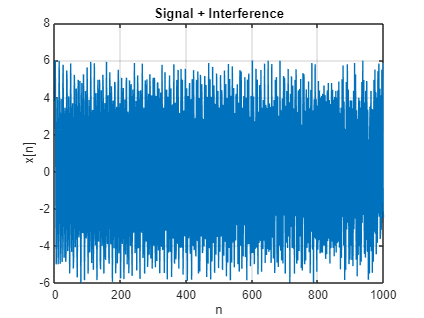

% Interference signal
w0 = pi/3+pi/6000*n;
i = 5*cos(w0.*n);
x = sn + i;
figure
plot(x)
xlabel('n')
ylabel('x[n]')
title('Signal + Interference')
grid on

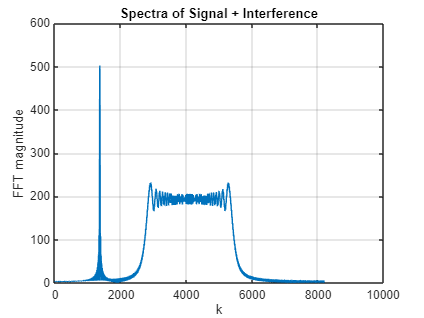

sifft = fft(x,16384);
sifft = sifft(1:end/2);

figure
plot(abs(sifft))
xlabel('k')
ylabel('FFT magnitude')
title('Spectra of Signal + Interference')
grid on

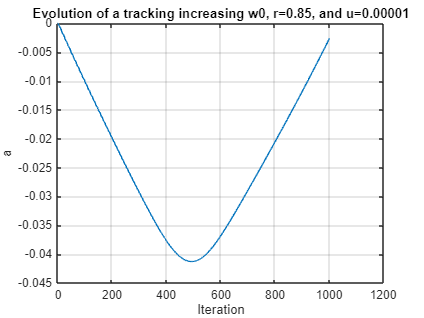

r = 0.85;
u = 0.00001;

a = zeros(1,N);
y = zeros(1,N);
xfilt = x;

for i=1:N
    if i==1
        e = x(i);
        y(i) = e;
        a(i+1) = a(i);
    elseif i==2
        e = x(i) + a(i)*x(i-1);
        y(i) = e - r*a(i)*y(i-1);
        a(i+1) = a(i) - u*y(i)*x(i-1);
    else
        e = x(i) + a(i)*x(i-1) + x(i-2);
        y(i) = e - r*a(i)*y(i-1) - r^2*y(i-2);
        a(i+1) = a(i) - u*y(i)*x(i-1);
    end
    if abs(a(i+1)) > 2
        a(i+1) = 0;
    end
    if i > 550
        num = [1 a(i) 1];
        den = [1 r*a(i) r^2];
        xfilt = filter(num,den,xfilt);
    end
end

figure
plot(a)
xlabel('Iteration')
ylabel('a')
title('Evolution of a tracking increasing w0, r=0.85, and u=0.00001')
grid on

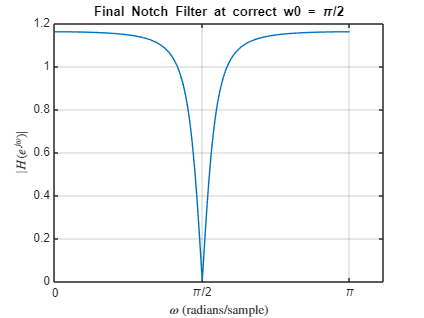


num = [1 a(end) 1];
den = [1 r*a(end) r^2];
[H,w] = freqz(num,den,1024);
figure
plot(w,(abs(H)))
xlabel('$\omega$ (radians/sample)','Interpreter','latex')
ylabel('$|H(e^{j\omega})|$','Interpreter','latex')
title('Final Notch Filter at correct w0 = \pi/2')
xticks([0 pi/2 pi])
xticklabels({'0', '\pi/2', '\pi'})
grid on

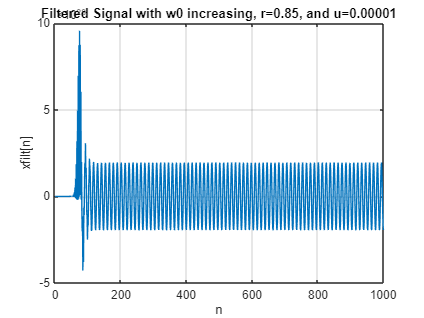


figure
plot(xfilt)
xlabel('n')
ylabel('xfilt[n]')
title('Filtered Signal with w0 increasing, r=0.85, and u=0.00001')
grid on

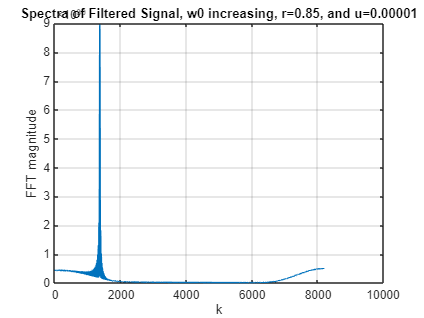


xfiltfft = fft(xfilt,16384);
figure
plot(abs(xfiltfft(1:end/2)))
xlabel('k')
ylabel('FFT magnitude')
title('Spectra of Filtered Signal, w0 increasing, r=0.85, and u=0.00001')
grid on